## Modulación Digital por Desplazamiento de Fase

En este sistema se envían señales con la misma frecuencia y amplitud, luego de módulo constante, pero con M posibles fases diferentes asociadas a los M símbolos del alfabeto utilizado. Cada uno de los símbolos se codificará n bits diferentes, siendo la relación entre n y M 𝑛 = log2 𝑀 En esta práctica prestaremos especial atención a la modulación QPSK, de cuatro niveles, cuya constelación es la que se muestra en la Figura 1.

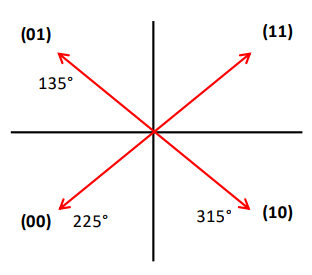

El nombre de QPSK viene de Quadrature Phase Shift Keying. La señal de cuatro niveles se construye como la superposición en fase y cuadratura de dos señales bifase BPSK (Binary Phase Shift Keying). 

En el paquete de funciones .m de Matlab que acompaña a la práctica se incluyen las de un modulador QPSK y de otro DQPSK, así como las de sus demoduladores correspondientes. Con la ayuda de estas funciones, el alumno deberá resolver los puntos restantes del apartado 2, comentando e interpretando los resultados que vaya obteniendo.

#### 2.1 Modulación QPSK

Compruebe el correcto funcionamiento de la función de modulación QPSK representando gráficamente mediante la función scatterplot el resultado de transmitir las cuatro secuencias binarias [1 1], [1 0], [0 1] y [0 0]. 

La función scatterplot representa los valores a su entrada en un plano complejo, por lo que es muy útil para ver gráficamente los símbolos producidos. Consulte la ayuda para conocer su funcionamiento. Asegúrese de que los símbolos producidos son coherentes con la constelación deseada. 

Asimismo, esta función es muy útil para analizar el efecto que tiene el ruido sobre la señal a transmitir, como veremos a continuación. 

%% =========================================================================
%% EJERCICIO 2.1: Modulación QPSK y Caracterización de Constelación
%% =========================================================================
clear; clc; close all;

parejas_bits = [1 1; 1 0; 0 1; 0 0];
txBits = reshape(parejas_bits', 1, []); 
xMod = moduladorQPSK(txBits);

% 1. Tabla de mapeo y símbolos
Bits_Transmitidos = ["1 1"; "1 0"; "0 1"; "0 0"];
I_Real            = real(xMod(:));
Q_Imag            = imag(xMod(:));
Modulo            = abs(xMod(:));
Fase_deg          = mod(angle(xMod(:)) * 180 / pi, 360);

tabla_ej21 = table(Bits_Transmitidos, I_Real, Q_Imag, Modulo, Fase_deg, ...
    'VariableNames', {'Bits', 'I', 'Q', 'Modulo', 'Fase_deg'});
disp(tabla_ej21);

    Bits     I     Q     Modulo    Fase_deg
    _____    __    __    ______    ________

    "1 1"     1     1    1.4142       45   
    "1 0"     1    -1    1.4142      315   
    "0 1"    -1     1    1.4142      135   
    "0 0"    -1    -1    1.4142      225   




% 2. Métricas de Capa Física y Espacio de Señales (ICAI Master Level)
d_min       = 2.0;                                   % Distancia euclídea mínima entre símbolos contiguos
Es          = mean(abs(xMod).^2);                   % Energía media de símbolo (Es = 2)
Eb          = Es / 2;                               % Energía media por bit (Eb = 1 -> 0 dB)
d_min_norm  = d_min / sqrt(Eb);                     % Distancia normalizada d_min / sqrt(Eb) = 2
PAPR_dB     = 10*log10(max(abs(xMod).^2) / Es);      % PAPR de la constelación (0 dB -> envolvente constante)
Eficiencia  = 2;                                    % bits/s/Hz teórica en banda base (Nyquist alpha=0)

tabla_metricas_21 = table(d_min, d_min_norm, Es, Eb, PAPR_dB, Eficiencia, ...
    'VariableNames', {'d_min', 'd_min_norm_Eb', 'Es', 'Eb', 'PAPR_dB', 'Eficiencia_bps_Hz'});
disp(tabla_metricas_21);

    d_min    d_min_norm_Eb    Es    Eb    PAPR_dB    Eficiencia_bps_Hz
    _____    _____________    __    __    _______    _________________

      2            2          2     1        0               2        



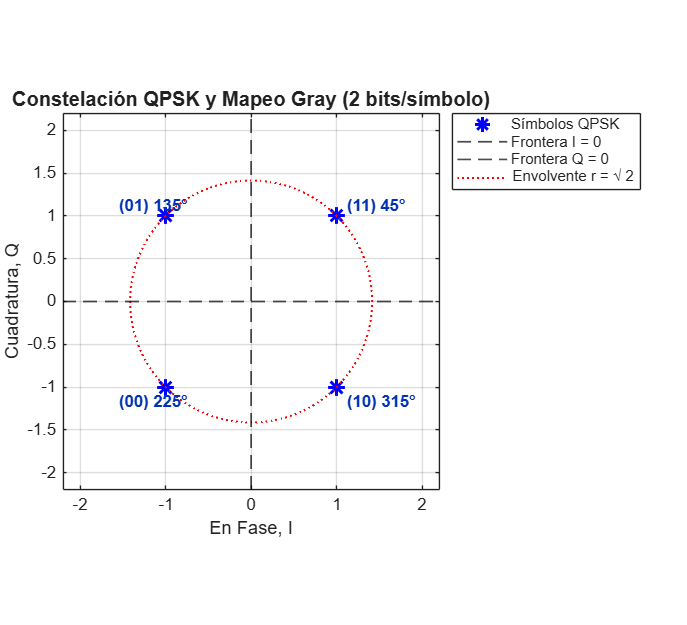


% 3. Gráfica de constelación en plano I-Q
figure('Color', 'w', 'Position', [150 150 550 500]);
ax = gca;
set(ax, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.85 0.85 0.85]);

plot(real(xMod), imag(xMod), 'b*', 'MarkerSize', 10, 'LineWidth', 1.8);
hold on; grid on; axis square;
axis([-2.2 2.2 -2.2 2.2]);

title('Constelación QPSK y Mapeo Gray (2 bits/símbolo)', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('En Fase, I', 'FontSize', 11);
ylabel('Cuadratura, Q', 'FontSize', 11);

xline(0, 'k--', 'LineWidth', 1);
yline(0, 'k--', 'LineWidth', 1);
th = linspace(0, 2*pi, 200);
plot(sqrt(2)*cos(th), sqrt(2)*sin(th), 'r:', 'LineWidth', 1.2);

etiquetas = {'(11) 45°', '(10) 315°', '(01) 135°', '(00) 225°'};
offset_x = [0.12,  0.12, -0.55, -0.55];
offset_y = [0.12, -0.18,  0.12, -0.18];
for idx = 1:length(xMod)
    text(real(xMod(idx)) + offset_x(idx), imag(xMod(idx)) + offset_y(idx), ...
        etiquetas{idx}, 'FontSize', 10, 'FontWeight', 'bold', 'Color', [0 0.2 0.7]);
end

legend({'Símbolos QPSK', 'Frontera I = 0', 'Frontera Q = 0', 'Envolvente r = \surd 2'}, ...
    'Location', 'northeastoutside', 'Color', 'w');

#### 2.2 modulación QPSK con ruido

Genere un vector de bits aleatorios y modúlelos en QPSK. Sobre el vector de símbolos modulados, añada ruido blanco gaussiano AWGN para simular el efecto del ruido presente en el receptor; la función awgn le será de utilidad. 

Haga una representación gráfica utilizando scatterplot al añadir un ruido con 5 dB, 10 dB y 15 dB de relación señal a ruido, SNR_dB. Muestre los gráficos obtenidos y coméntelos. ¿Cómo afecta el ruido a la generación de bits erróneos?

%% =========================================================================
%% EJERCICIO 2.2: QPSK en Canal AWGN con Métrica EVM
%% =========================================================================
Nbits = 4000;
rng(42);
txBits_rand = randi([0 1], 1, Nbits);
xMod_rand = moduladorQPSK(txBits_rand);

k = log2(4);
SNR_vect_dB = [5, 10, 15];
simb_ideales = [1+1j, -1+1j, -1-1j, 1-1j];

EbN0_dB_calc    = (SNR_vect_dB - 10*log10(k))';
EbN0_lin        = 10.^(EbN0_dB_calc / 10);
sigma_ruido     = sqrt(10.^(-SNR_vect_dB(:) / 10));
margen_frontera = 1.0 ./ sigma_ruido;

% Métricas avanzadas: EVM y Probabilidad de Error de Símbolo vs Bit
EVM_porc        = (1 ./ sqrt(10.^(SNR_vect_dB(:)/10))) * 100;
EVM_dB          = -SNR_vect_dB(:);
BER_teorica     = qfunc(sqrt(2 * EbN0_lin));
SER_teorica     = 2*BER_teorica - BER_teorica.^2;   % Ps exacta en QPSK

tabla_ej22 = table(SNR_vect_dB', EbN0_dB_calc, sigma_ruido, margen_frontera, ...
    EVM_porc, BER_teorica, SER_teorica, ...
    'VariableNames', {'SNR_dB', 'EbN0_dB', 'Sigma_Ruido', 'Margen_d_sigma', ...
    'EVM_porc', 'BER_Teorica', 'SER_Teorica'});
disp(tabla_ej22);

    SNR_dB    EbN0_dB    Sigma_Ruido    Margen_d_sigma    EVM_porc    BER_Teorica    SER_Teorica
    ______    _______    ___________    ______________    ________    ___________    ___________

       5      1.9897       0.56234          1.7783         56.234       0.037679       0.073938 
      10      6.9897       0.31623          3.1623         31.623      0.0007827      0.0015648 
      15       11.99       0.17783          5.6234         17.783      9.361e-09     1.8722e-08 



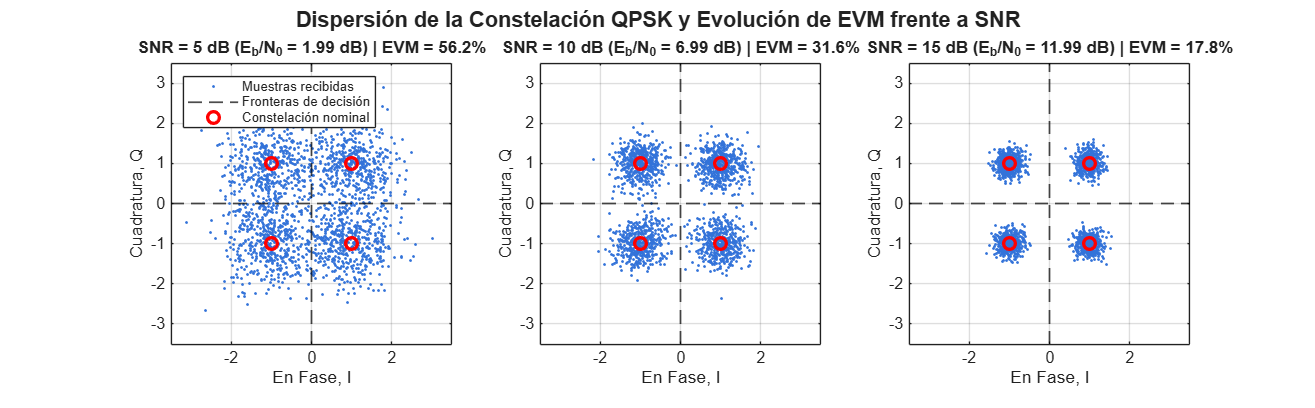


% Subplots 1x3 ya validados
figure('Color', 'w', 'Position', [80 200 1350 420]);
for i = 1:length(SNR_vect_dB)
    snr_i = SNR_vect_dB(i);
    rx_noisy = awgn(xMod_rand, snr_i, 'measured');

    subplot(1, 3, i);
    ax = gca;
    set(ax, 'Color', 'w', 'XColor', 'k', 'YColor', 'k', 'GridColor', [0.85 0.85 0.85]);

    plot(real(rx_noisy), imag(rx_noisy), '.', 'Color', [0.2 0.45 0.85], 'MarkerSize', 5);
    hold on; grid on; axis square;
    axis([-3.5 3.5 -3.5 3.5]);

    xline(0, 'k--', 'LineWidth', 1.1);
    yline(0, 'k--', 'LineWidth', 1.1);
    plot(real(simb_ideales), imag(simb_ideales), 'ro', 'MarkerSize', 7, 'LineWidth', 2);

    title(sprintf('SNR = %d dB (E_b/N_0 = %.2f dB) | EVM = %.1f%%', ...
        snr_i, EbN0_dB_calc(i), EVM_porc(i)), 'FontSize', 10, 'FontWeight', 'bold');
    xlabel('En Fase, I'); ylabel('Cuadratura, Q');

    if i == 1
        legend({'Muestras recibidas', 'Fronteras de decisión', '', 'Constelación nominal'}, ...
            'Location', 'northwest', 'FontSize', 8, 'Color', 'w');
    end
end
sgtitle('Dispersión de la Constelación QPSK y Evolución de EVM frente a SNR', ...
    'FontSize', 13, 'FontWeight', 'bold');

#### 2.3 Cadena de modulación-demodulación QPSK y DQPSK 

Empleando el vector de bits aleatorios del ejercicio anterior, genere una señal modulada en QPSK y a continuación demodúlela con la función del demodulador QPSK. Compruebe que en ausencia de ruido los bits recibidos son idénticos a los transmitidos, y por tanto BER = 0. Realice el mismo ejercicio, pero con modulación y demodulación diferencial DQPSK.

%% =========================================================================
%% EJERCICIO 2.3: Cadena Completa QPSK vs DQPSK (Canal Ideal)
%% =========================================================================

% Rama QPSK Coherente
xMod_QPSK   = moduladorQPSK(txBits_rand);
rxBits_QPSK = demoduladorQPSK(xMod_QPSK);
numErr_QPSK = sum(abs(txBits_rand - rxBits_QPSK));
BER_QPSK    = numErr_QPSK / length(txBits_rand);

% Rama DQPSK Diferencial
xMod_DQPSK   = moduladorDQPSK(txBits_rand);
rxBits_DQPSK = demoduladorDQPSK(xMod_DQPSK);
numErr_DQPSK = sum(abs(txBits_rand - rxBits_DQPSK));
BER_DQPSK    = numErr_DQPSK / length(txBits_rand);

% Tabla en formato string
Esquema           = ["QPSK Coherente"; "DQPSK Diferencial"];
Bits_Tx           = [length(txBits_rand); length(txBits_rand)];
Errores_Bit       = [numErr_QPSK; numErr_DQPSK];
BER_Obtenida      = [BER_QPSK; BER_DQPSK];
Condicion_Canal   = ["Canal ideal (sin ruido)"; "Canal ideal (sin ruido)"];
Sincronizacion    = ["Bucle de Costas / PLL obligatorio"; "No coherente (detección de fase relativa)"];

tabla_ej23 = table(Esquema, Bits_Tx, Errores_Bit, BER_Obtenida, Condicion_Canal, Sincronizacion, ...
    'VariableNames', {'Esquema', 'Bits_Tx', 'Errores', 'BER', 'Canal', 'Requisito_Sincronismo'});
disp(tabla_ej23);

          Esquema          Bits_Tx    Errores    BER              Canal                         Requisito_Sincronismo           
    ___________________    _______    _______    ___    _________________________    ___________________________________________

    "QPSK Coherente"        4000         0        0     "Canal ideal (sin ruido)"    "Bucle de Costas / PLL obligatorio"        
    "DQPSK Diferencial"     4000         0        0     "Canal ideal (sin ruido)"    "No coherente (detección de fase relativa)"

